clear
load clown
clown(20,319)

ans = 0.1554

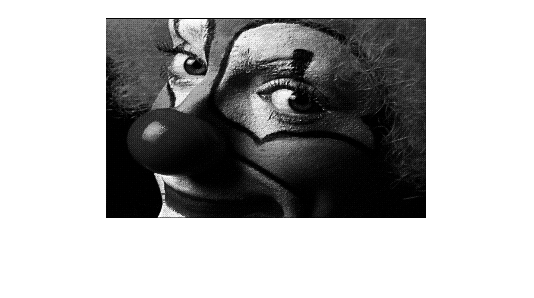

imshow(clown)


new = Shear(clown, 0.1, 0.5)

new =     0.4742    0.3787    0.4263    0.4396    0.2791    0.3209    0.2791    0.3787    0.2791    0.3209    0.3661    0.2791    0.3209    0.2791    0.3209    0.3209    0.1554    0.4396    0.6060    0.7912    0.8516    0.7912    0.7912    0.2664    0.2664    0.2664    0.1902    0.7341    0.9305    0.9305    0.9305    0.9305    0.9305    0.9305    0.9305    0.7912    0.9305    0.7912    0.9305    0.9305    0.9305    0.9305    0.9305    0.9305    0.9305    0.9305    0.9305    0.9305    0.8516    0.7912
    0.4263    0.4742    0.3344    0.4263    0.2791    0.4263    0.3787    0.2791    0.4263    0.2791    0.3787    0.3209    0.3344    0.3209    0.3209    0.2791    0.3344    0.3209    0.2273    0.5380    0.7912    0.7912    0.7912    0.6060    0.4396    0.4396    0.2664    0.6060    0.7912    0.9305    0.9305    0.9305    0.9305    0.9305    0.9305    0.7912    0.7341    0.9305    0.7912    0.9305    0.7912    0.9305    0.7912    0.8516    0.8516    0.7912    0.9305    0.7912    0.9305   

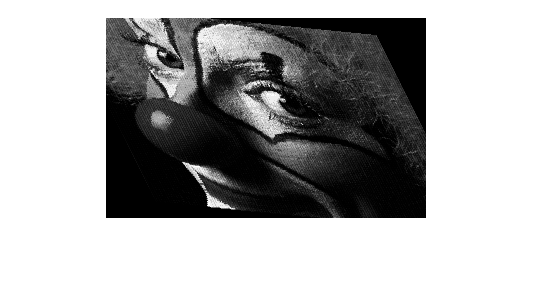

imshow(new, [] )

function Out = Shear(In, xshear, yshear)

% Calculating number of rows and colums in the input image
[rows, cols] = size(In);

% Forward shear matrix
tm = [1, xshear;
    yshear, 1];

% Performing the inverse of the transformation matrix for reverse mapping
itm = inv(tm);

% Initialise output
Out = zeros(rows, cols, class(In));
 
% Locating the centre point of the input image 
cp = [((rows)/2); ((cols)/2)];

for r = 1:rows          % Desitnation row
    for c = 1:cols      % Destination col
        p = [r; c];     % Destination point
        
        % Reverse mapping equation
        tp = itm * (p - cp) + cp;   % Source

        % Nearest Neighbour
        rs = round(tp(1));      % rs = row of source
        cs = round(tp(2));      % cs = column of source


        % Bound Check
        if rs < 1 || rs > rows || cs < 1 || cs > cols
            Out(r,c) = 0;       % Paint Black
        else
            Out(r,c) = In(rs,cs);   % Paint from source
        end
    end
end
end